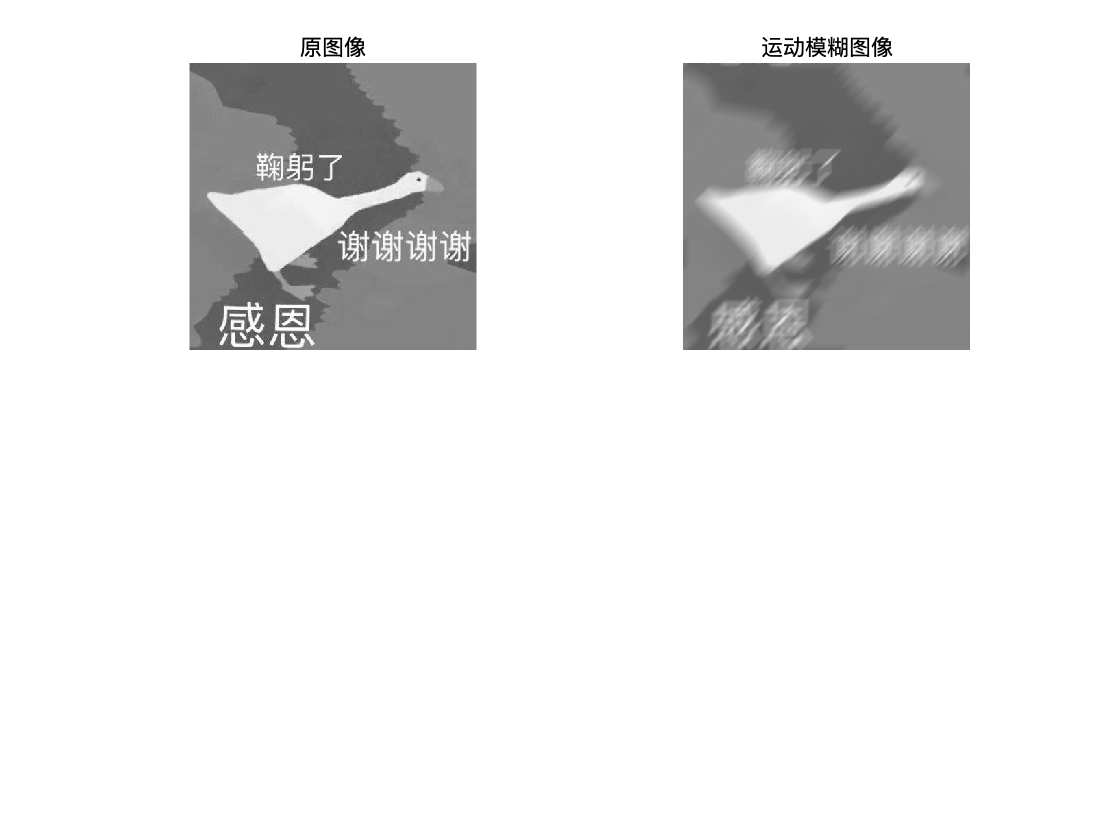

A=rgb2gray(imread('pic.jpg'));
A=im2double(A);
subplot(221);imshow(A);title("原图像")

LEN=30;THEAT=45;
PSF=fspecial('motion',LEN,THEAT);
MF=imfilter(A,PSF,'circular','conv');
subplot(222);imshow(MF);title("运动模糊图像")


imwrite(MF,'pic2.jpg');

% 估计函数复原

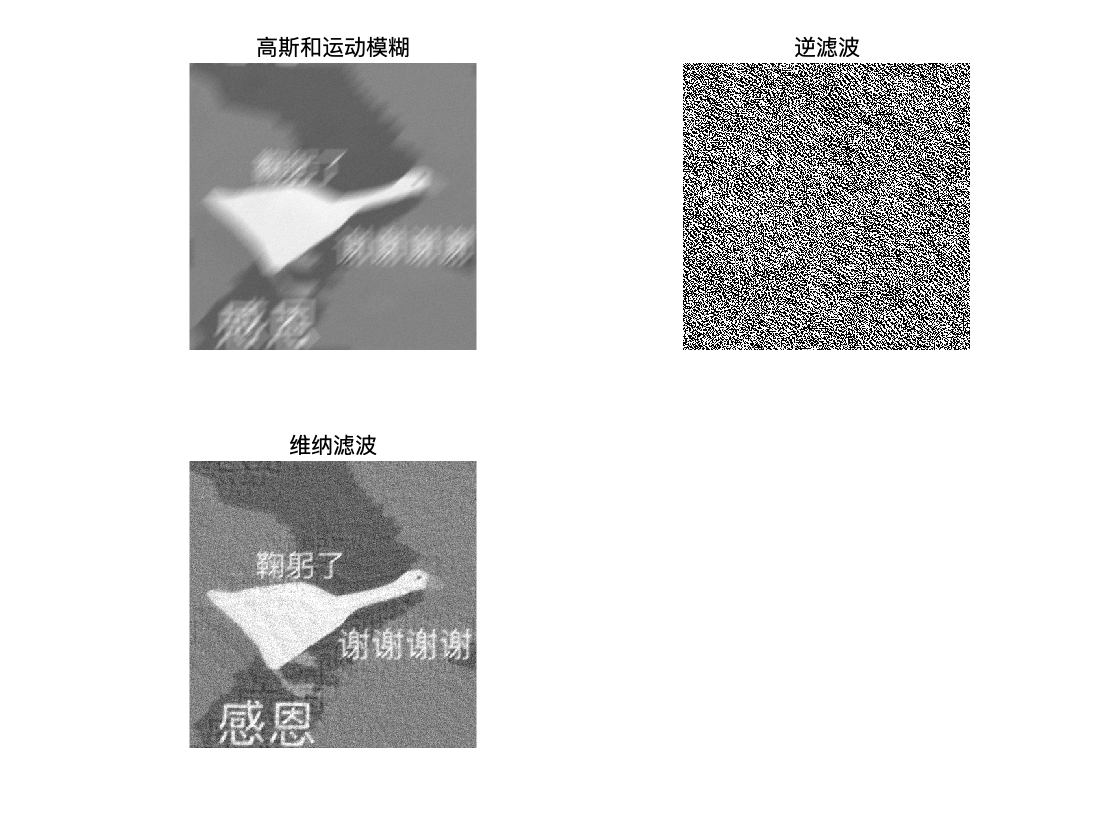

% 逆滤波和维纳滤波复原
m=0;
noise_var=0.0001;
MFN=imnoise(MF,'gaussian',m,noise_var);
figure();
subplot(221);imshow(MFN);title('高斯和运动模糊');

nilvbo=deconvwnr(MFN,PSF,0);
subplot(222);imshow(nilvbo);title('逆滤波')

NSR = noise_var / var(A(:));
weina=deconvwnr(MFN,PSF,NSR);
subplot(223),imshow(weina);title('维纳滤波');